# Motor Generator 2

Copyright 2021 The Mathworks, Inc.

## Open the Model

mdl = "MotorGenerator2Basic_test_harness";
if not(bdIsLoaded(mdl)), open_system(mdl); end

MotorGenerator2Basic_setup

## Load Inputs to Workspace

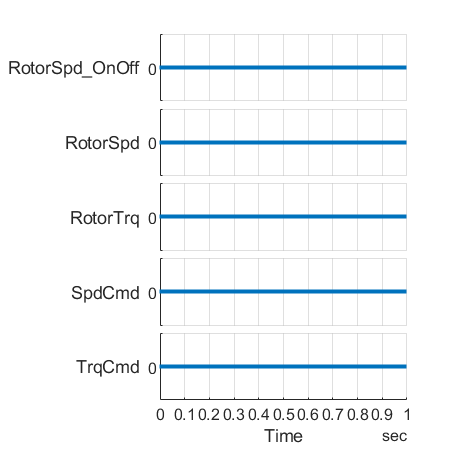

fig = figure;
[inputSignals_MG2, inputBus_MG2, t_end] = ...
  MotorGenerator2Basic_inputs( ...
    "PlotParent",fig, "InputPattern","all_zero" );

## Run Simulation

% Override initial conditions and block parameters
initial.motorGenerator2_speed_rpm = 0;
initial.vehicleSpeed_kph = 0;

% Set simulation input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

Inputs

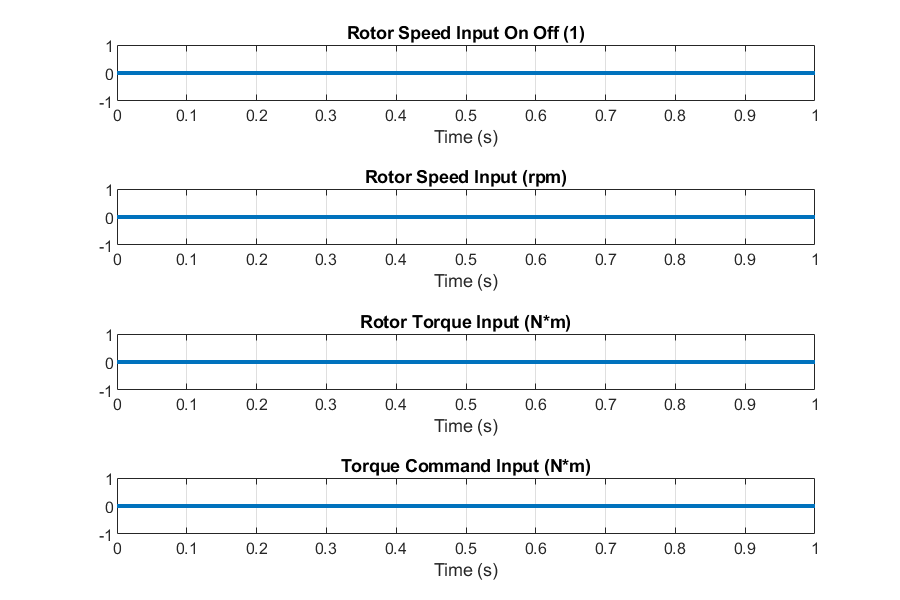

fig = figure;
MotorGenerator2Basic_plot_result_inputs( ...
  "PlotParent",fig, "Dataset",out.logsout)
fig.Position(3:4) = [600 400];  % widht height

Outputs

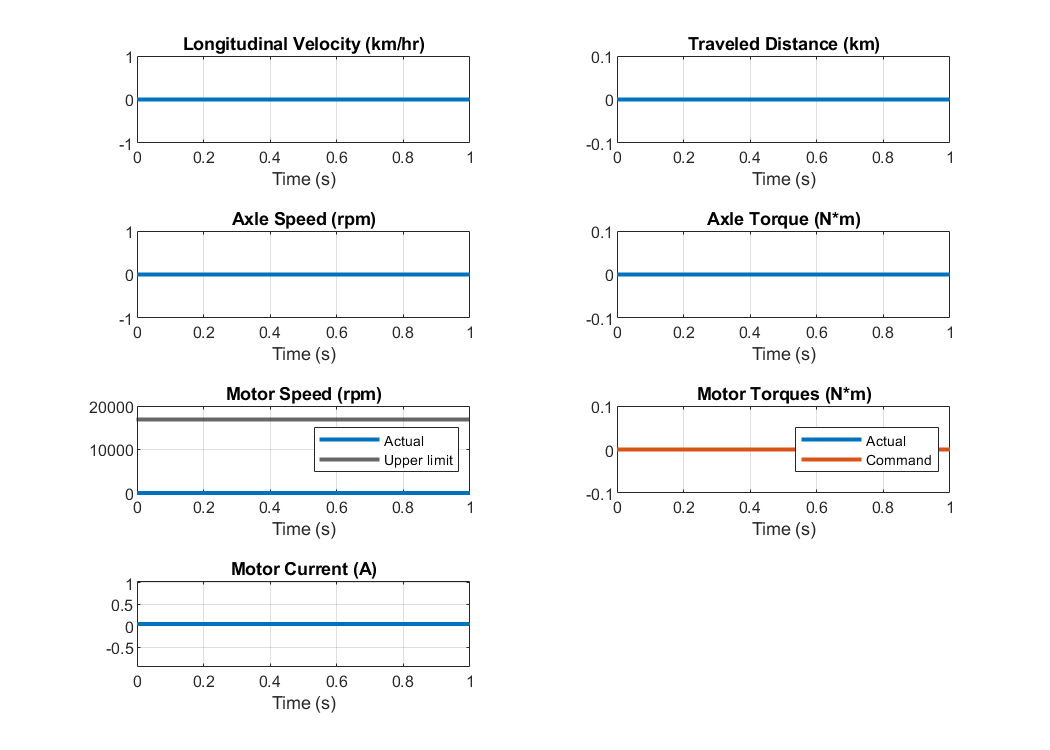

fig = figure;
MotorGenerator2Basic_plot_result_outputs( ...
  "PlotParent",fig, "Dataset",out.logsout)
fig.Position(3:4) = [700 500];  % width height